# Correspondence analysis

In file [ExamplesCA.mlx](matlab:open('ExamplesCA.mlx')) we have described how to use a series of FSDA functions to compute and plot the output of correspondence analysis. In this file we show how to call the interactive APP which through its GUI enables to dinamically interact

#### Example the clothes dataset

Marco Riani, Anthony C. Atkinson, Francesca Torti, Aldo Corbellini, Robust Correspondence Analysis, *Journal of the Royal Statistical Society Series C: Applied Statistics*, Volume 71, Issue 5, November 2022, Pages 1381–1401, [https://doi.org/10.1111/rssc.12580](https://doi.org/10.1111/rssc.12580)

The data are in the context of European Union (EU) international trade, which is regulated in compliance with the World Trade Organization ([1994](about:blank<javascript:;>)), and are available publicly in the COMEXT database of the European statistical office (Eurostat).

The clothes data contains a contingency table between the 28 member states of the European Union (data collected well before Brexit) and 5 price segments. These are occurrences of country trade flows, for a wide set of clothes: x1 denotes the lowest price segment and x5 the highest price segment and In all there are 4373 counts.

load clothes.mat
disp(clothes)

          x1     x2    x3    x4    x5
          ___    __    __    __    __

    GB    134    76    43    50    49
    SK    173    62    20    23    16
    BG     67    76    48    36    23
    IE     11    21    31    36    52
    BE     25    32    57    60    58
    ES     32    42    40    67    67
    PL     20    35    31    41    41
    FI     10    16    23    23    24
    GR     54    28    29    30    23
    HU     12    19    14    15    20
    SI      9    10    14    20    23
    NL     52    43    38    47    54
    IT     21    36    33    30    36
    RO     85    74  

The data considered cover a period of several years, ending in 2017.

disp(clothes.Properties.Description)

The clothes data contains a contingency table between the 28 member states of the European Union (data collected well before Brexit) and 5 price segments. These are occurrences of country trade flows, for a wide set of clothes: x1 denotes the lowest price segment and x5 the highest price segment and In all there are 4373 counts.


The main interest in the analysis is in the row profiles: does the proportion of flows in each price segment vary in any meaningful way between countries? 

Summary
             Singular_value     Inertia     Accounted_for    Cumulative
             ______________    _________    _____________    __________

    dim_1        0.38033         0.14465       0.83291        0.83291  
    dim_2        0.13623        0.018557       0.10686        0.93976  
    dim_3       0.079538       0.0063262      0.036427        0.97619  
    dim_4       0.064303       0.0041349      0.023809              1  

ROW POINTS
Results for dimension: 1
           Scores      CntrbPnt2In    CntrbDim2In
          _________    ___________    ___________

    GB     -0.41105      0.094025       0.94458  
    SK     -0.92168       0.394

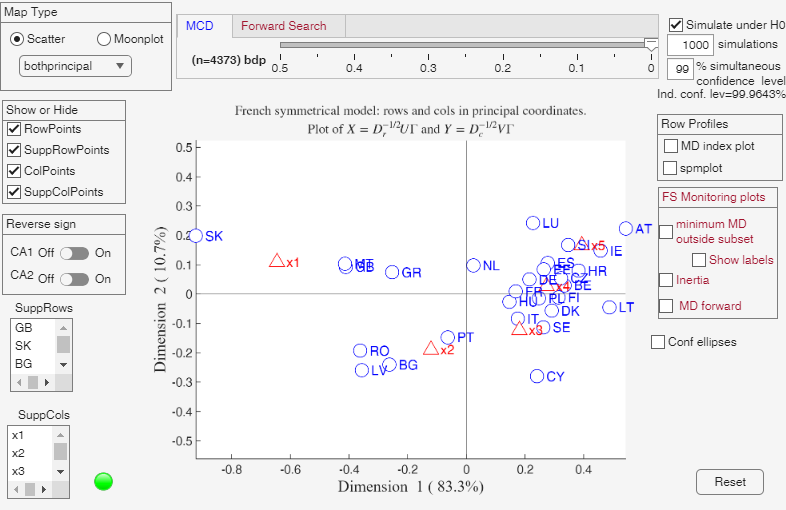

CorAnaAPP(clothes)